clc;clear;close all;


## -------------------------------读取点云---------------------------------

warning off
% load('ShiCe.mat')
% points = [points(3,:);points(1,:);points(2,:)];
% P3 = [P3(3),P3(1),P3(2)];
% P4 = [P4(3),P4(1),P4(2)];
% 
% 
% load('data.mat')
% points = [data(:,1)';data(:,2)';data(:,3)';];



azimuth = 5.135899059569828;
elevation = 1.57897350050879;

r = 1;
x0 = r.*cos(azimuth).*cos(elevation);
y0 = r.*cos(azimuth).*sin(elevation);
z0 = r.*sin(azimuth);
Tao = [x0,y0,z0]

Tao =    -0.0034    0.4109   -0.9117


P3 = [0.698625642652000,1.04004032326448,-0.573794783259771]+Tao;
P4 = [0.710558671267955,-0.419236813348415,-0.777745273229581]-Tao;


num = 8;
laynum = 5;

% 测试 生成 一个截面 测点
Point_out = generate_unit_circle_with_normal_vector2(azimuth,elevation,num,laynum,P3,P4);


% % 测试 生成 所有测点
% Point_tset = Generate_multi_layered_measurement_points(Point_out,num,laynum,P3,P4);


% 测试 测点的拟合
tic
[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Point_out,P3,P4)

Mcenter =     0.0002   -0.0044   -0.0020


MTaon =     0.0037   -0.4168    0.9090


Mradial = 1.0000

Err_every =    -0.0035   -0.0052   -0.0045   -0.0019    0.0015    0.0043    0.0052    0.0038   -0.0018   -0.0026   -0.0023   -0.0010    0.0008    0.0021    0.0026    0.0019    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0018    0.0026    0.0023    0.0010   -0.0008   -0.0022   -0.0026   -0.0019    0.0036    0.0052    0.0045    0.0019   -0.0015   -0.0043   -0.0052   -0.0038


Bottom_round_center1 =    -0.0069    0.8095   -1.7768


Bottom_round_center2 =     0.0019   -0.2004    0.4256


toc

历时 3.906511 秒。


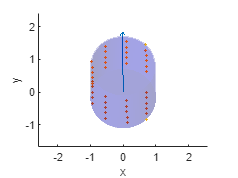



 
% 计算两个中心点u1、u2
u1 = Bottom_round_center1;
u2 = Bottom_round_center2;





figure
hold on
% 绘制圆柱面
plotcylinder(u1,u2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
quiver3(0,0,0,5*x0,5*y0,5*z0)
scatter3(Point_out(1,:),Point_out(2,:),Point_out(3,:),5,"filled");
scatter3([P3(1),P4(1)],[P3(2),P4(2)],[P3(3),P4(3)],5,"filled");